## ROS2 Package ID

folderpath = fullfile(pwd,"EECE5554/LAB4/src/") % Access folder & build packages

folderpath = "/home/qianw/EECE5554/LAB4/src/"

ros2genmsg(folderpath) % This probably isnt doing anything

Identifying message files in folder '/home/qianw/EECE5554/LAB4/src'.Validating message files in folder '/home/qianw/EECE5554/LAB4/src'.Done.
Done.
[2/2] Generating MATLAB interfaces for custom message packages... Done.
Running colcon build in folder '/home/qianw/EECE5554/LAB4/src/matlab_msg_gen/glnxa64'.
Build in progress. This may take several minutes...
Build succeeded.build_log.

bagselect2=ros2bagreader("EECE5554/LAB4/data/data_driving2") % Access data

bagselect2 =   ros2bagreader with properties:

           FilePath: '/home/qianw/EECE5554/LAB4/data/data_driving2'
      AvailableBags: "data_driving2.db3"
          StartTime: 1.7430e+09
            EndTime: 1.7430e+09
    AvailableTopics: [2×3 table]
    AvailableFrames: {0×1 cell}
        MessageList: [34171×3 table]
        NumMessages: 34171


## Data Extraction

fields = readMessages(bagselect2);
bSel = select(bagselect2,"Topic","/imu");
%imu = readMessages(bSel,'DataFormat','struct');
a = fields{1};
IMUmsgs= readMessages(bSel);
a2 = IMUmsgs{1}

a2 = struct with fields:
    MessageType: 'imu_interface/IMUmsg'
         header: [1×1 struct]
            imu: [1×1 struct]
      mag_field: [1×1 struct]
         rawstr: '$VNYMR,+034.865,-005.825,-011.625,-00.0421,-00.0219,+00.1037,+00.503,-00.463,-09.337,-00.003607,-00.006419,+00.055982*63'



fields2 = readMessages(bagselect2);
bSel2 = select(bagselect2,"Topic","/gps");
%imu = readMessages(bSel,'DataFormat','struct');
b = fields{1};
GPSmsgs= readMessages(bSel2);
b2 = GPSmsgs{1};

testPoint = cellfun(@(m) struct(m.header.stamp),fields);
gyroPoints = cellfun(@(m) struct(m.imu.angular_velocity),IMUmsgs);
accelPoints = cellfun(@(m) struct(m.imu.linear_acceleration),IMUmsgs);
orientPoints = cellfun(@(m) struct(m.imu.orientation),IMUmsgs);
magPoints = cellfun(@(m) struct(m.mag_field.magnetic_field),IMUmsgs);

lati = cellfun(@(m) double(m.latitude),GPSmsgs);
long = cellfun(@(m) double(m.longitude),GPSmsgs);
%alt = cellfun(@(m) string(m.altitude),GPSmsgs)
%alti = str2int2(extract(alt,))

VNYMR = cellfun(@(m) string(m.rawstr),IMUmsgs);
%plot(imuPoints)

%gyroData = gyroPoints{:,[2 3 4]}
gyroPoints(1)

ans = struct with fields:
    MessageType: 'geometry_msgs/Vector3'
              x: -0.0036
              y: -0.0064
              z: 0.0560


xGyro = arrayfun(@(m) double(m.x),gyroPoints);
yGyro = arrayfun(@(m) double(m.y),gyroPoints);
zGyro = arrayfun(@(m) double(m.z),gyroPoints);


accelPoints(1)

ans = struct with fields:
    MessageType: 'geometry_msgs/Vector3'
              x: 0.5030
              y: -0.4630
              z: -9.3370


xAccel = arrayfun(@(m) double(m.x),accelPoints);
yAccel = arrayfun(@(m) double(m.y),accelPoints);
zAccel = arrayfun(@(m) double(m.z),accelPoints);

orientPoints(1)

ans = struct with fields:
    MessageType: 'geometry_msgs/Quaternion'
              x: -0.0814
              y: -0.0785
              z: 0.2927
              w: 0.9495


xOrient = arrayfun(@(m) double(m.x),orientPoints);
yOrient = arrayfun(@(m) double(m.y),orientPoints);
zOrient = arrayfun(@(m) double(m.z),orientPoints);
wOrient = arrayfun(@(m) double(m.w),orientPoints);

magPoints(1)

ans = struct with fields:
    MessageType: 'geometry_msgs/Vector3'
              x: -4.2100e-06
              y: -2.1900e-06
              z: 1.0370e-05


xMag = arrayfun(@(m) double(m.x),magPoints)*10^4;
yMag = arrayfun(@(m) double(m.y),magPoints)*10^4;
zMag = arrayfun(@(m) double(m.z),magPoints)*10^4;

## Gauss to Degrees Raw Data

Bx = xMag%* 10^4;

Bx =    -0.0421
   -0.0425
   -0.0432
   -0.0431
   -0.0434
   -0.0431
   -0.0425
   -0.0422
   -0.0421
   -0.0415


By = yMag%* 10^4;

By =    -0.0219
   -0.0234
   -0.0246
   -0.0254
   -0.0254
   -0.0242
   -0.0236
   -0.0224
   -0.0217
   -0.0204


Bz = zMag%* 10^4;

Bz =     0.1037
    0.1024
    0.1016
    0.1017
    0.1010
    0.1019
    0.1026
    0.1034
    0.1041
    0.1049



% Magnitude
B = sqrt(Bx.^2 + By.^2 + Bz.^2);

% Direction
azimuth = atan2(By, Bx);
MagRaw_degrees = rad2deg(azimuth);
MagRaw = mod(MagRaw_degrees, 360); 

## Gauss to Degrees: Corrected Data

CxMag = xMag;
CyMag = yMag;
CzMag = zMag;

c00 = 1.1;
c01 = 0;
c02 = 0;
c10 = 0;
c11 = 1.2;
c12 = 0;
c20 = 0;
c21 = 0;
c22 = 1;

bh0 = -0.05;   %*10^-6;
bh1 = -0.0225; %*10^-6;
bh2 = 0;

cor_xMag = c00*(CxMag-bh0);% 
cor_yMag = c11*(CyMag-bh1);% 
cor_zMag = c22*(CzMag-bh2);% 

Bx2 = cor_xMag;%*
By2 = cor_yMag;%*
Bz2 = cor_zMag;%*

% Magnitude
B2 = sqrt(Bx2.^2 + By2.^2 + Bz2.^2);

% Direction
azimuth = atan2(By2, Bx2);

MagCorrect_degrees = rad2deg(azimuth);
MagCorrect = mod(MagCorrect_degrees, 360); 

## Magnometer Angle Plot & Low Pass Filter

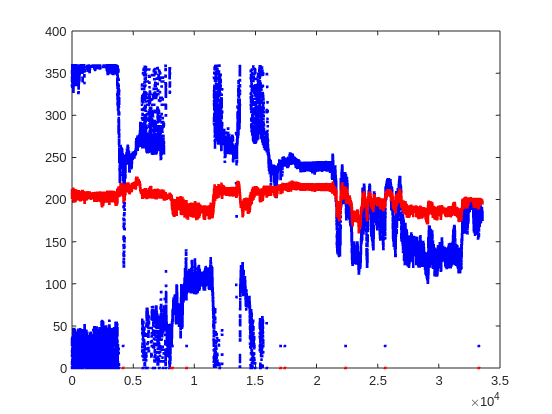

figure
plot(MagCorrect,'b.')
hold on
plot(MagRaw,'r.')

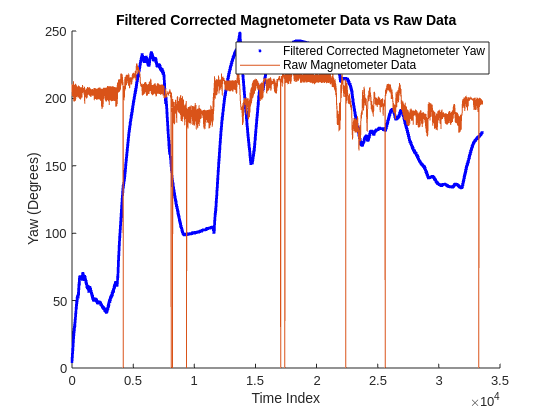

%plot(MagCorrect_degrees,'.')
%plot(MagRaw_degrees,'.')

x = MagCorrect;   
alpha = 0.001;   % Smoothing factor (0 < alpha < 1), smaller = smoother

% Preallocate output array
MagLP = zeros(size(x));
MagLP(1) = x(1);  % Initialize with first value

% Apply low-pass filter
for i = 2:length(x)
    MagLP(i) = alpha * x(i) + (1 - alpha) * MagLP(i-1);
end

figure
hold on
plot(MagLP,'b.')
plot(MagRaw)
%plot(MagCorrect,'m.')
title('Filtered Corrected Magnetometer Data vs Raw Data')
legend('Filtered Corrected Magnetometer Yaw','Raw Magnetometer Data')
xlabel('Time Index')
ylabel('Yaw (Degrees)')
saveas(gcf,'Lab4MagnetometerCorrected.png')

## Yaw thingy  & High Pass Filter

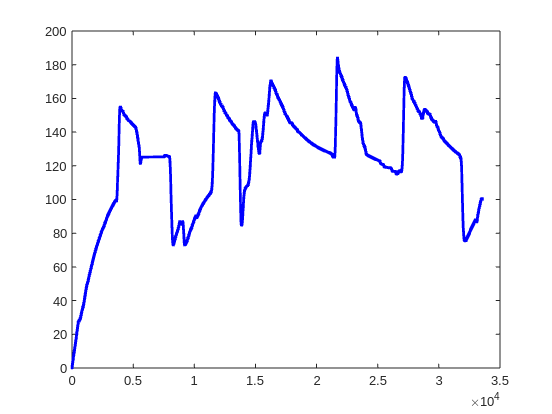

Yaw = xGyro;
Pitch= yGyro;
Roll = zGyro;

YawThing = cumtrapz(Yaw);
PitchThing = cumtrapz(Pitch);
RollThing = cumtrapz(Roll);

Total = sqrt(Yaw.^2+Pitch.^2+Roll.^2);
TotalThing = cumtrapz(Total);


alpha = 0.99955;  % Smoothing factor (0 < alpha < 1), higher = more high-passing

% Preallocate output
YawF = zeros(size(YawThing));
YawF(1) = YawThing(1);  % Initialize
for i = 2:length(YawThing)
    YawF(i) = alpha * (YawF(i-1) + YawThing(i) - YawThing(i-1));
end

PitchF = zeros(size(PitchThing));
PitchF(1) = PitchThing(1);  % Initialize
for i = 2:length(PitchThing)
    PitchF(i) = alpha * (PitchF(i-1) + PitchThing(i) - PitchThing(i-1));
end

RollF = zeros(size(YawThing));
RollF(1) = RollThing(1);  % Initialize
for i = 2:length(RollThing)
    RollF(i) = alpha * (RollF(i-1) + RollThing(i) - RollThing(i-1));
end

TotalF = zeros(size(TotalThing));
TotalF(1) = TotalThing(1);  % Initialize
for i = 2:length(TotalThing)
    TotalF(i) = alpha * (TotalF(i-1) + TotalThing(i) - TotalThing(i-1));
end

figure
%plot(YawF,'r.')
%plot(PitchF,'g.')
plot(RollF,'b.') % Use this as the Yaw Thing 

%plot(TotalF,'y.')

## Mag vs Yaw Plot

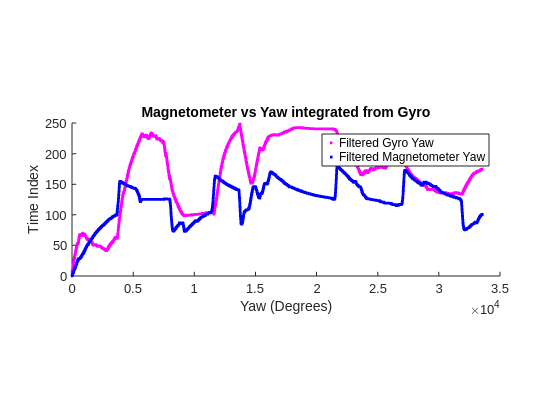

% THIS WORKS CONTINUE SENSOR FUSION WITH ROLL
figure
hold on
plot(MagLP,'m.')
plot(RollF,'b.')
daspect([1 0.02 1])

%plot(rad2deg(zOrient),'g.')
%plot(TotalF,'y.')
title('Magnetometer vs Yaw integrated from Gyro')
legend('Filtered Gyro Yaw','Filtered Magnetometer Yaw')
xlabel('Yaw (Degrees)')
ylabel('Time Index')
saveas(gcf,'Lab4MagvsYawGyro.png')

## Magnometer (MagCorrect), Gyro Yaw (RollF), Raw Euler Data, Fused (Complementary)

% Fused
a = 0.7;
Fuse = a*RollF + (1-a)*MagLP

Fuse =     1.4209
    1.5648
    1.7055
    1.8439
    1.9817
    2.1229
    2.2663
    2.3043
    2.3437
    2.3858


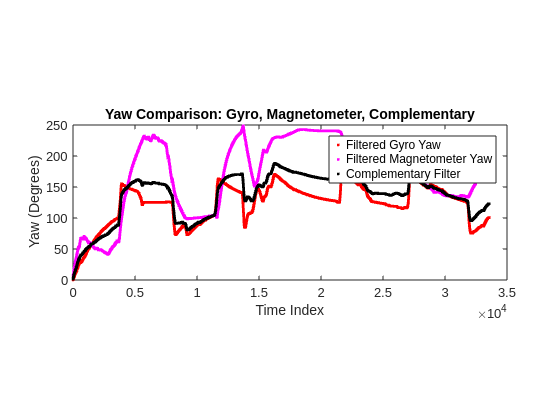


figure
plot(RollF,'r.')
hold on
plot(MagLP,'m.')
plot(Fuse,'k.')
daspect([1 0.02 1])
title('Yaw Comparison: Gyro, Magnetometer, Complementary')
xlabel('Time Index')
ylabel('Yaw (Degrees)')
legend('Filtered Gyro Yaw','Filtered Magnetometer Yaw','Complementary Filter')
saveas(gcf,'Lab4MagYawFusion.png')



q = quaternion(wOrient, xOrient, yOrient, zOrient);
eul = eulerd(q, 'ZYX', 'frame');
EulerYaw   = (eul(:,1));
EulerF_R = unwrap(deg2rad(EulerYaw))

EulerF_R =     0.6085
    0.6099
    0.6113
    0.6127
    0.6141
    0.6154
    0.6168
    0.6182
    0.6196
    0.6210


EulerF_D = rad2deg(EulerF_R)

EulerF_D = 1.0e+03 *

    0.0349
    0.0349
    0.0350
    0.0351
    0.0352
    0.0353
    0.0353
    0.0354
    0.0355
    0.0356


%figure
%plot(EulerYaw,'b.')

alp = 0.9992

alp = 0.9992

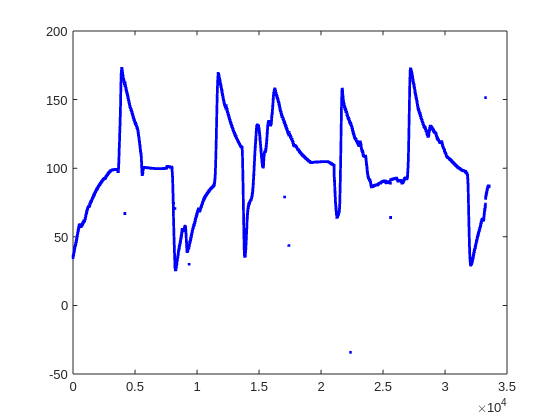

EulerF = zeros(size(EulerF_D));
EulerF(1) = EulerF_D(1);  % Initialize
for i = 2:length(EulerF_D)
    EulerF(i) = alp * (EulerF(i-1) + EulerF_D(i) - EulerF_D(i-1));
end
figure
plot(EulerF,'b.')

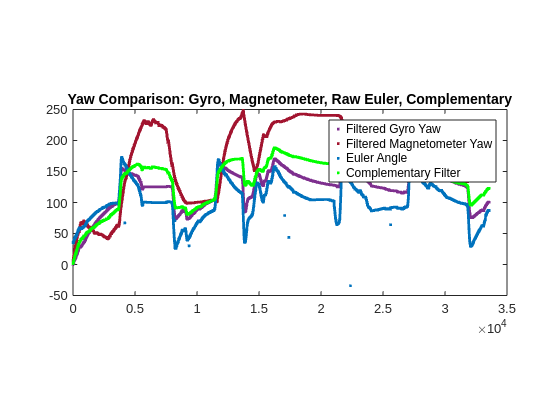


figure
plot(RollF,'.','Color',[0.4940 0.1840 0.5560])
hold on
plot(MagLP,'.','Color',[0.6350 0.0780 0.1840])
plot(EulerF,'.','Color',[0 0.4470 0.7410])
plot(Fuse,'g.')
daspect([10 0.2 10])

title('Yaw Comparison: Gyro, Magnetometer, Raw Euler, Complementary')
legend('Filtered Gyro Yaw','Filtered Magnetometer Yaw','Euler Angle','Complementary Filter')
exportgraphics(gcf,'Lab4Part1All.png','Resolution',300)